X = X_air_sg_01;
data = X(1:num_train, :);
label = y(1:num_train);

% Common parameter settings
% opts.k  = 5;      % Number of k in K-nearest neighbor
opts.N  = 50;     % number of solutions
opts.T  = 150;    % maximum number of iterations
% Parameters of PSO
opts.c1  = 0.5;         % cognitive factor
opts.c2  = 0.5;         % social factor 
opts.w   = 0.9;       % inertia weight

% Ratio of validation data
ho = 0.2;
% Divide data into training and validation sets
HO = cvpartition(label,'HoldOut',ho); 
opts.Model = HO; 

% Perform feature selection 
FS = jfs('pso',data,label,opts);


Iteration 2 Best (PSO)= 0.021137
Iteration 3 Best (PSO)= 0.021137
Iteration 4 Best (PSO)= 0.021137
Iteration 5 Best (PSO)= 0.021137
Iteration 6 Best (PSO)= 0.020930
Iteration 7 Best (PSO)= 0.020930
Iteration 8 Best (PSO)= 0.020749
Iteration 9 Best (PSO)= 0.020645
Iteration 10 Best (PSO)= 0.020541
Iteration 11 Best (PSO)= 0.020438
Iteration 12 Best (PSO)= 0.020386
Iteration 13 Best (PSO)= 0.004119
Iteration 14 Best (PSO)= 0.004016
Iteration 15 Best (PSO)= 0.003938
Iteration 16 Best (PSO)= 0.003834
Iteration 17 Best (PSO)= 0.003834
Iteration 18 Best (PSO)= 0.003834
Iteration 19 Best (PSO)= 0.003834
Iteration 20 Best (PSO)= 0.003834
Iteration 21 Best (PSO)= 0.003782
Iteration 22 Best (PSO)= 0.003782
Iteration 23 Best (PSO)= 0.003731
Iteration 24 Best (PSO)= 0.003731
Iteration 25 Best (PSO)= 0.003679
Iteration 26 Best (PSO)= 0.003653
Iteration 27 Best (PSO)= 0.003601
Iteration 28 Best (PSO)= 0.003601
Iteration 29 Best (PSO)= 0.003523
Iteration 30 Best (PSO)= 0.003446
Iteration 31 Best (PS


% Define index of selected features
sf_idx = FS.sf

sf_idx =      1     5     6    10    12    20    23    25    27    29    32    35    39    40    43    44    45    49    50    56    59    62    63    66    68    70    71    73    79    82    84    94    99   105   106   107   112   118   122   126   132   135   136   144   150   153   154   157   163   166



% Accuracy  
Acc = jknn(data(:,sf_idx),label,opts); 


 Accuracy: 100 %

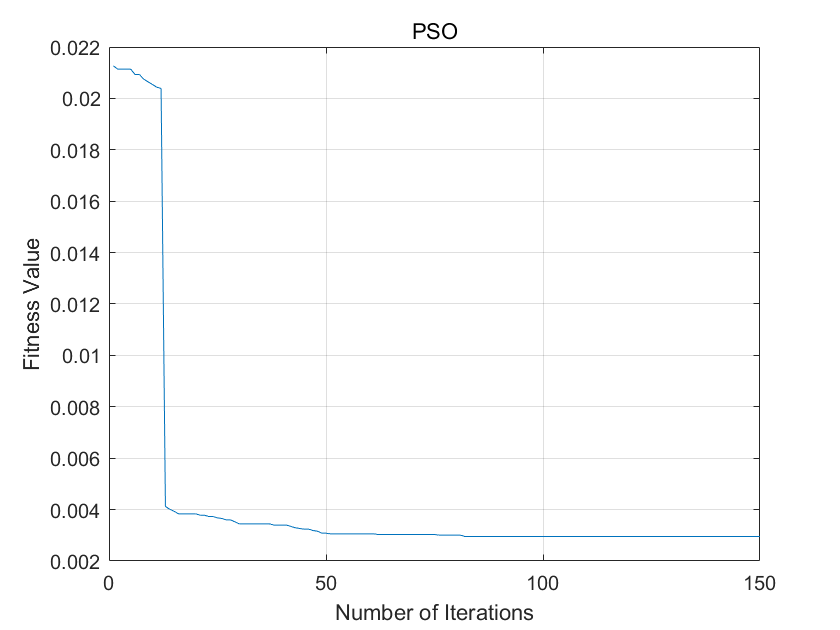


% Plot convergence
plot(FS.c); grid on;
xlabel('Number of Iterations'); 
ylabel('Fitness Value');
title('PSO');

vsel_pso = sf_idx;
data_pso = X(:, vsel_pso);
[~, starch0] = min(abs(effshift - 477));
[~, starch] = min(abs(vsel_pso - starch0));

[spa_ind] = feature_spa(data_pso, starch, 24);
vsel_pso_spa = vsel_pso(spa_ind)

vsel_pso_spa =     20   325   334   333   320   189   319   188   183   174   337   177   282   318   193   349   166   248   277   264   350   275   386   359


effshift(vsel_pso_spa)

ans =        477.22       1596.8       1627.1       1623.7       1579.9       1120.8       1576.5       1117.2         1099       1066.1       1637.2       1077.1       1450.1       1573.1       1135.3       1677.3       1036.7       1331.6       1432.8       1387.6       1680.6       1425.9       1799.3       1710.5
